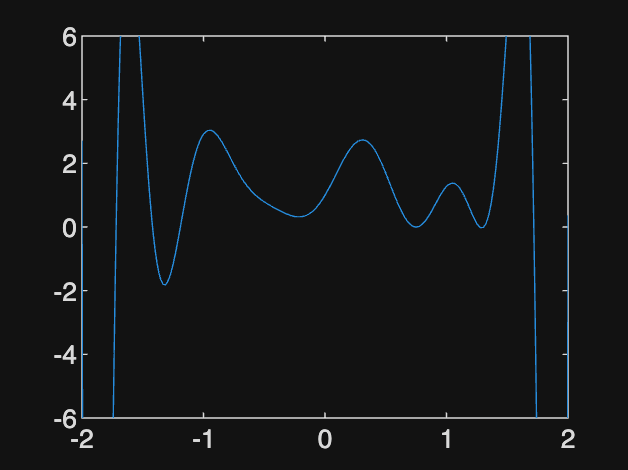

x=linspace(-2,2,15);
f=exp(sin(5.5.*x));
u=linspace(-2,2,500);

v=barycent1(x,f,u);
plot(u,v);
ylim([-6,6]);

function v=barycent(x,f,u)
    n = length(x);
    w=ones(n,1);

    for j=1:n
        for i=1:n
            if i~=j
                w(j)=w(j)/(x(j)-x(i));
            end
        end
    end
   
    v=zeros(size(u));
    for k=1:length(u)
        uk=u(k);
        % check for same node in u
        find_index=find(uk==x,1);
        if ~isempty(find_index)
            v(k)=f(find_index);
        else
            numerator= sum((w.*f) ./ (uk-x));
            denominator= sum(w ./ (uk-x));
            v(k)=numerator/denominator;
        end
    end
end

function ye = barycent1(x,y,xe)
% ye = modlagr(x,y,xe)
% find interpolating polynomial for data x,y and evaluate at points xe
% input:
%   vectors x,y: given data points
%   vector xe:   evaluation points
% output: 
%   vector ye: values of interpolating polynomial at points xe

% uses modified Lagrange formula 

% compute w_j
w = zeros(size(x)); 
for j=1:length(x);   
  w(j) = 1;   
  for k=1:j-1     
    w(k) = w(k)/(x(k)-x(j));     
    w(j) = w(j)/(x(j)-x(k));   
  end 
end 

% evaluate modified Lagrange formula
s = zeros(size(xe));
P = ones(size(xe));
equalnode = zeros(size(xe));  
for j=1:length(x)
  d = xe - x(j);
  equalnode(d==0) = j;        % where xe coincides with node: store node number
  s = s + y(j)*w(j)./d;       % division by zero where xe coincides with node
  P = P.*d;
end
ye = P.*s;                    

% fix ye for xe-values which coincide with nodes
ind = (equalnode>0);          % indices where we had division by zero
ye(ind) = y(equalnode(ind));  % replace with nodal values
end
